%{
optimise.mlx
Uses wind turbine equations to calculate the optimal rotor design given input parameters.

Manually determine variables in `config` struct, variables in `params` will
be optimised automatically.

Assumptions:
    max_number_blades = 3
    max_rotor_radius = 0.5
    max_chord = 0.2
    visc_air = 15.06e-6
    C_D = 0 (for initial calculations)
    Chord distribution is linear

Callum Morrison, 2020
%}

clear

% Setup fixed optimisation values
config = struct( ...
    "N_elements", 30, ...                % Number of blade elements
    "rotor_start_radius", 0.12, ...      % Minimum blade radius
    "ratio_closeness", 0.01, ...          % Required closeness before blade convergence
    "ratio_closeness_halflife", 5, ...   % Number of iterations before ratio is halved
    "fluid_density", 1.225, ...          % Density of air
    "v_free_stream", 3, ...              % Velocity of wind tunnel
    "viscosity_kinematic", 15.06e-6 ...  % Viscosity of air
    );

load('S822_CL_Lookup.mat', "S822_CL_Lookup")
load('S822_CD_Lookup.mat', "S822_CD_Lookup")
load('S822_Re_Values.mat', "S822_Re_Values")
load('S822_Alpha_Values.mat', "S822_Alpha_Values")

C_L_lookup = struct( ...
    "C_L", S822_CL_Lookup, ...
    "C_D", S822_CD_Lookup, ...
    "angle_of_attack", S822_Alpha_Values, ...
    "reynolds", S822_Re_Values ...
    );

population_size = 500;

% Limit starting params somewhat (e.g. angle of attack). If best results
% come from a maximum or minimum value, it may be necessary to increase the
% range to find the optimal solution.
rotor_radius = rand([population_size, 1]) * (0.5 - 0.15) + 0.15;   % [0.15 0.5]
number_blades = randi(3, [population_size, 1]);                    % [1 2 3]
tip_speed_ratio = rand([population_size, 1]) * 4 + 1;              % [1 5]
angle_of_attack = deg2rad(rand([population_size, 1]) * 5 + 5);     % [5 10]
chord_root = rand([population_size, 1]) * (0.2 - 0.01) + 0.01;     % [0.01 0.2]
chord_tip = rand([population_size, 1]) * (0.2 - 0.01) + 0.01;      % [0.01 0.2]

C_P = zeros(population_size, 1);
data = zeros(config.N_elements, 5, population_size);

% Initialise iteration variables
generation = 1;
max_generations = 10;
fitness = 0;
fitness_closeness = 0.1;
results = zeros([1, 8]);
halflife = 1;
mutation_probability = 0.05;

while ~(all(fitness + fitness_closeness > 1) && all(fitness - fitness_closeness < 1)) && generation < max_generations
    
    % Increase ratio precision if needed
    if mod(generation, config.ratio_closeness_halflife) == 0
        config.ratio_closeness = config.ratio_closeness / 2;
        halflife = halflife + 1
    end

    % Calculate all outcomes for given parameters
    parfor i = 1:population_size
        temp_params = struct( ...
            "rotor_radius", rotor_radius(i), ...
            "number_blades", number_blades(i), ...
            "tip_speed_ratio", tip_speed_ratio(i), ...
            "angle_of_attack", angle_of_attack(i), ...
            "chord_root", chord_root(i), ...
            "chord_tip", chord_tip(i) ...
            );
        
        [data(:, :, i), C_P(i)] = solve_blade(config, temp_params, C_L_lookup);
    end

    % Replace NaN with 0; the worst score
    C_P(isnan(C_P)) = 0;
    
    % Combine solutions into a N * k matrix for easier manipulation
    population = [C_P, rotor_radius, number_blades, tip_speed_ratio, angle_of_attack, chord_root, chord_tip];
    
    % Rank solutions
    [~, order] = sort(C_P, 'descend');
    population = population(order, :);
    best_data = data(:, :, order(1));
    best_population = population(order(1), :);
    
    % Calculate variation in population
    variation = mean(var(rescale(population,'InputMin',min(population),'InputMax',max(population))));
    
    fprintf("Fitness: %0.4f\n", population(1, 1));
    fprintf("Variance: %0.4f\n", variation);
    
    results = [results; variation, population(1, :)];
    disp(population(1, 2:end));
    
%     % Eliminate worst 1/2
%     population = population(1:population_size * 0.1, :);
    
%     % Crossover algirithm for new children
%     parents = [randperm(population_size * 0.1)', randperm(population_size * 0.1)'];
    children = zeros([population_size, 6]);

    parents = [randsample(1:population_size, population_size, true, rescale(population(:, 1)))', ...
       randsample(1:population_size, population_size, true, rescale(population(:, 1)))'];
    
    for i = 1:population_size
        % Select parents
        parent = randi(2, [6, 1]);
        % parent_2 = mod(parent_1 - 2, 2) + 1
        
        child = parents(i, parent);
        genes = diag(population(child, 2:end));
        children(i, :) = genes';
    end

    % Mutation algorithm for remaining children
    for i = 1:population_size
        % Generate mutations for each factor, average with the existing child
        % A weighted mean will bias towards the existing children with half life
        % Insert mutiated child back into children population
%         children(i + population_size / 2, :) = [ ...
%             mean([rand() * (0.5 - 0.15) + 0.15, repmat(children(i, 1), [1, halflife])]), ...
%             round(mean([rand() * 3 + 0.5, children(i, 2)])), ...
%             mean([rand() * 4 + 1, repmat(children(i, 3), [1, halflife])]), ...
%             mean([deg2rad(rand() * 5 + 5), repmat(children(i, 4), [1, halflife])]), ...
%             mean([rand() * (0.2 - 0.01) + 0.01, repmat(children(i, 5), [1, halflife])]), ...
%             mean([rand() * (0.2 - 0.01) + 0.01, repmat(children(i, 6), [1, halflife])]) ...
%         ];

        mutations = [ ...
            rand() * (0.5 - 0.15) + 0.15, ...
            randi(3), ...
            rand() * 4 + 1, ...
            deg2rad(rand() * 5 + 5), ...
            rand() * (0.2 - 0.01) + 0.01, ...
            rand() * (0.2 - 0.01) + 0.01 ...
        ];

        for j = 1:6
            mutate = rand() < mutation_probability;
            
            if mutate
                children(i, j) = mutations(j);
            end
        end
    end
    
    % Update original variables for next iteration
    rotor_radius = children(:, 1);
    number_blades = children(:, 2);
    tip_speed_ratio = children(:, 3);
    angle_of_attack = children(:, 4);
    chord_root = children(:, 5);
    chord_tip = children(:, 6);
    
    generation = generation + 1;
end

Fitness: 3.9994


Variance: 0.0875


    0.4903    3.0000    3.5979    0.1207    0.1762    0.0791



Fitness: 4.5022


Variance: 0.0890


    0.4564    1.0000    2.1980    0.1659    0.1962    0.1242



Fitness: 5.6547


Variance: 0.0821


    0.4962    3.0000    2.3132    0.1633    0.1848    0.1756



Fitness: 5.6507


Variance: 0.0750


    0.4962    3.0000    3.3178    0.1582    0.1455    0.0821



halflife = 2

Fitness: 5.6313


Variance: 0.0734


    0.4916    1.0000    2.4811    0.1645    0.1998    0.1242



Fitness: 5.8555


Variance: 0.0697


    0.4993    1.0000    2.6470    0.1727    0.1848    0.1125



Fitness: 5.9120


Variance: 0.0667


    0.4962    3.0000    2.6470    0.1633    0.1998    0.1232



Fitness: 5.9120


Variance: 0.0639


    0.4962    3.0000    2.6470    0.1633    0.1998    0.1232



Fitness: 5.9120


Variance: 0.0656


    0.4962    1.0000    2.6470    0.1633    0.1998    0.1232



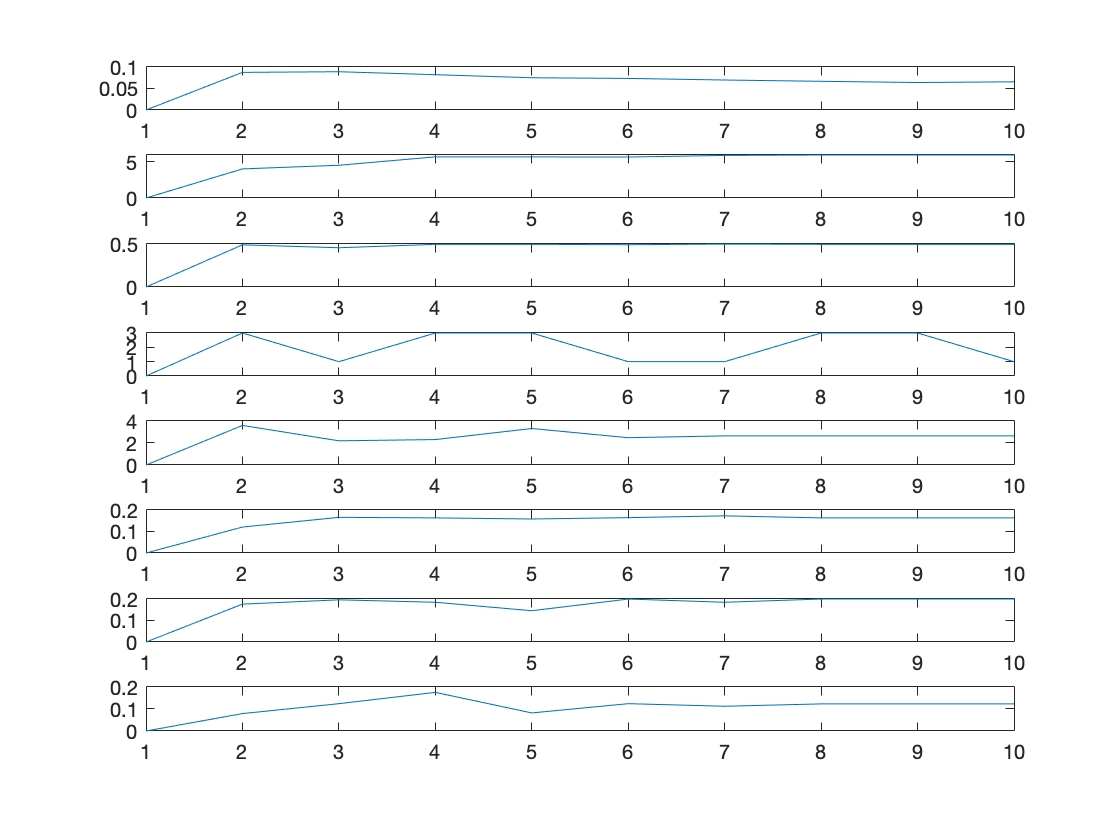

    
% % Check that Betz limit has not been surpassed
% if best_population(1) > 0.593
%     error("The Betz limit has been exceeded. Check your calculations.")
% end

for i = 1:size(results, 2)
    subplot(size(results, 2), 1, i)
    plot(results(:, i));
end

load('S822_Points.mat', "S822")

chord = linspace(best_population(6), best_population(7), config.N_elements)';
pitch = best_data(:, 4);
radius = linspace(config.rotor_start_radius, best_population(2), config.N_elements)';

profile = zeros(3, length(S822.x), config.N_elements);

% figure('Name', '3D Profile')
% clf
% hold on
% for i = 1:config.N_elements
%     
%     % Scale the profile to the correct chord length
%     profile(:, :, i) = [S822.x' .* chord(i); -S822.y' .* chord(i); radius(i) .* ones(1, size(profile, 2))];
%     
%     % Generate rotation matrix
%     R = [cos(-pitch(i) + pi/2) -sin(-pitch(i) + pi/2); sin(-pitch(i) + pi/2) cos(-pitch(i) + pi/2)];
%         
%     % Rotate the profile to the correct pitch angle
%     profile(1:2, :, i) = R * profile(1:2, :, i);
% 
%     scatter3(profile(1, :, i), profile(2, :, i), profile(3, :, i), ".")
%     axis equal
% end
% hold off

for i = 1:size(profile, 3)
    writematrix([profile(:, :, i)]', join(["points\profile", i, ".csv"], ""));
end

% % Invert matrix to convert to valid data format
% profile_out = zeros(size(profile, 2) * size(profile, 3), 3);
% blocksize = size(profile, 2);
% for i = 1:size(profile, 3)
%     profile_out(i + (i-1) * blocksize:i + i * blocksize - 1, :) = profile(:, :, i)';
% end
% 
% writematrix(profile_out, "profile.csv")
% writematrix(profile_out, "profile.dat", 'Delimiter','tab')
